## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 09 - Example 04 - Laoding of Scissor Mechanism**

In the previous example, we showed how to simulate the deployment a scissor mechanism. Here, we want to see how we can capture the load-carrying behavior of the same system. 

 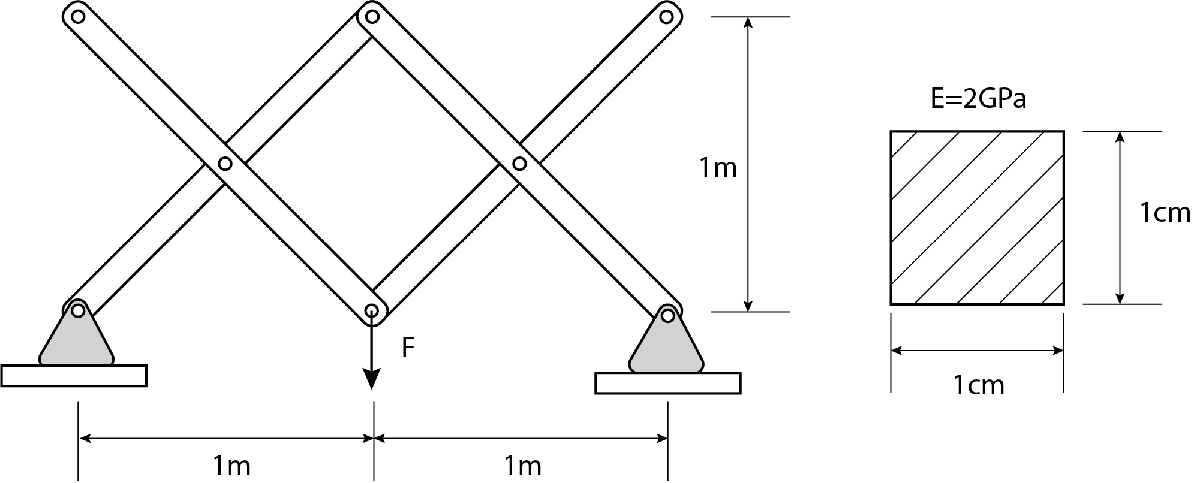

The above figure shows the loaing set up. Please do notice that the support information is changed. Now, both ends are fixed support - this will turn the mechanism into a structure. 

The set up of the simulation is mostly the same as the previous one so we will skip uncessary descriptions. 

clear all;
clc;
close all;

%% Initialize the truss
% Define the nodes
H=1; % Height of the truss
L=1; % Length of each span
barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

% We will also solve for the bending stiffness of the frame
I=1/12*0.01^4;
% When using four segment to represent a frame, 
% three rotational springs are used
% Using Larry Howell's pseudo rigid body model
% We can convert the bending stiffness to spring stiffness
barL=sqrt(H^2+L^2);
kspr=3*barE*I/barL;

Define all the objects for the elements we need to use

% Define the node object
node=Elements_Nodes;
% Create the bar object
bar=CD_Elements_Bars;
% Create the 3-node rot spring
rot_spr_3N=CD_Elements_RotSprings_3N;

% Create tje truss Assembly
assembly=Assembly_2D_Mechanism;
% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;
assembly.rot_spr_3N=rot_spr_3N;

Here, the nodal coordinates of this example is the same as Example 02.

%% Define the nodal coordinates
% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0*L 0 0; 
                      1*L 0 0;
                      2*L 0 0; % Node 3
                      0*L 0 H;
                      1*L 0 H; 
                      2*L 0 H; % Node 6
                      0.5*L 0 0.5*H; 
                      1.5*L 0 0.5*H; % Node 8
                      0.25*L 0 0.25*H;
                      0.75*L 0 0.25*H;
                      1.25*L 0 0.25*H;
                      1.75*L 0 0.25*H; % Node 12
                      0.25*L 0 0.75*H;
                      0.75*L 0 0.75*H;
                      1.25*L 0 0.75*H;
                      1.75*L 0 0.75*H; % Node 16
                      ];

We can plot the node for inspection.

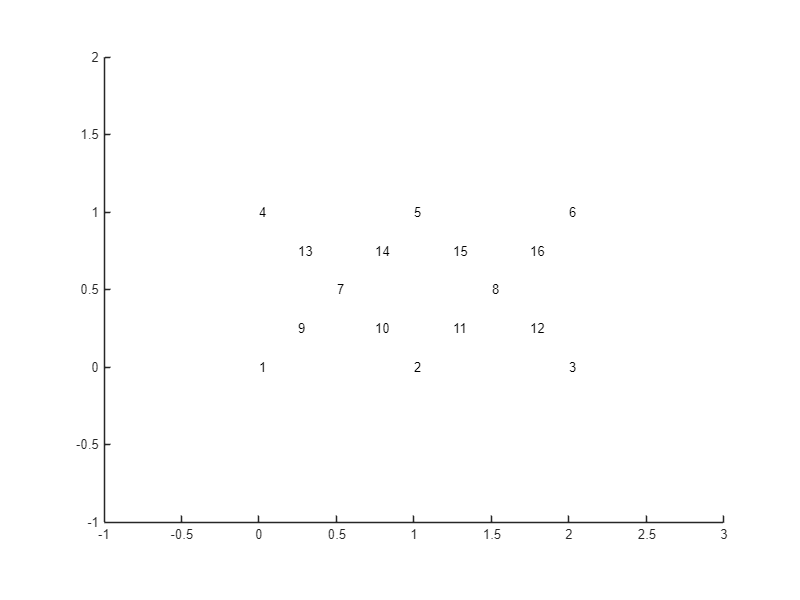

% Set up the plotting function for inspection
plots=Plot_2D_Mechanism();
plots.assembly=assembly;
% We will plot for the 2D mechnism assembly

plots.displayRange=[-1;3;-1;1;-1;2]; 
% Range of the plot
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

% Plot the nodal coordinates for inspection
plots.Plot_Shape_Node_Number()

We will continue to defing the bar and rotational springs. Please note that this process is also the same as Example 02.

% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[1,9;
                 7,9;
                 7,14;
                 14,5; % 4 bars
                 4,13;
                 13,7;
                 7,10;
                 10,2; % 8 bars
                 2,11;
                 11,8;
                 8,16;
                 16,6; % 12 bars
                 5,15;
                 15,8;
                 8,12;
                 12,3;]; % 16 bars

% Define the area of the bars
% We have a total of 16 bars
bar.A_vec=barA*ones(16,1);
bar.E_vec=barE*ones(16,1);

Let's first plot the bar elements to see if everything looks good. 

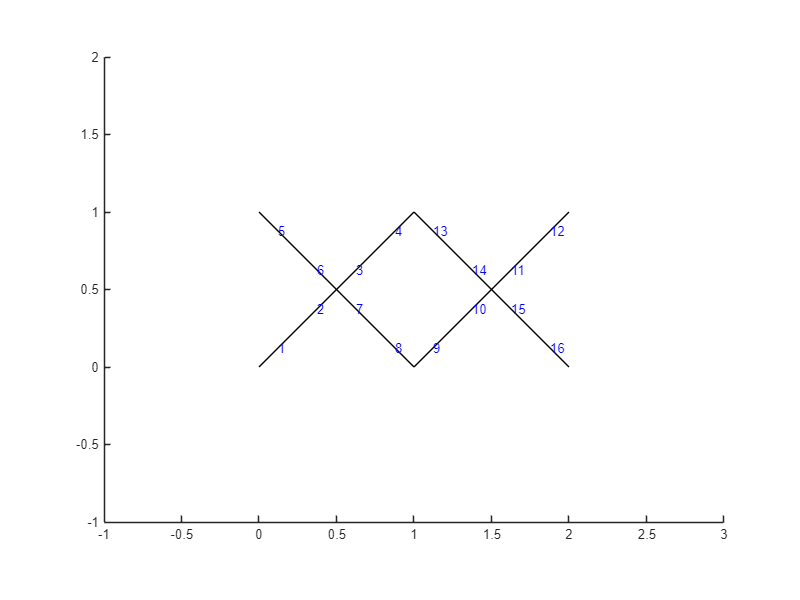

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Set up the 
plots.Plot_Shape_Bar_Number()

% Define how rotational springs are connected
rot_spr_3N.node_ijk_mat=[1 9 7;
                         9 7 14;
                         7 14 5; % 3 springs
                         4 13 7; 
                         13 7 10; 
                         7 10 2; % 6 springs
                         2 11 8; 
                         11 8 16; 
                         8 16 6; % 9 springs
                         5 15 8;  
                         15 8 12; 
                         8 12 3;]; % 12 springs

Here, we add the #13 spring to control the deployment. 

% We add another #13 spring to control the deployment
rot_spr_3N.node_ijk_mat=[rot_spr_3N.node_ijk_mat;
                         9 7 13];
% We also want to use a smaller delta step for higher accuracy
rot_spr_3N.delta=10^-7

rot_spr_3N =   CD_Elements_RotSprings_3N with properties:

             node_ijk_mat: [13×3 double]
            rot_spr_K_vec: []
    theta_stress_free_vec: [0×1 double]
        theta_current_vec: [0×1 double]
                    delta: 1.0000e-07


We next defing the other properties of rotational springs and plot the springs.

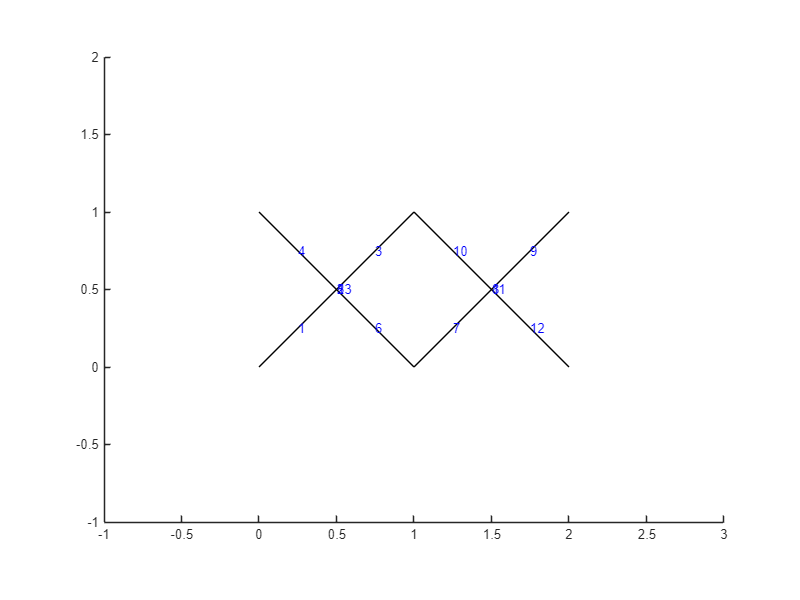

% Define rotational stiffness
rot_spr_3N.rot_spr_K_vec=kspr*ones(13,1);
% Initialize the entire assembly again for the new rot-spring
assembly.Initialize_Assembly();
% Plot the rotational spring number
plots.Plot_Shape_Spr_Number

Here, because we want to study the loading behavior, we need the "NR_Loading" solver. Please note that the support information is not the same as the Example 02. I encourage you to compare them to get a better understanding of the support definition. 

%% Set up the loading solver
nr=Solver_NR_Loading;
nr.assembly=assembly;
nr.supp=[1,1,1,1;
         2,0,1,0;
         3,1,1,1;
         4,0,1,0;
         5,0,1,0;
         6,0,1,0;
         7,0,1,0;
         8,0,1,0;
         9,0,1,0;
         10,0,1,0;
         11,0,1,0;
         12,0,1,0;
         13,0,1,0;
         14,0,1,0;
         15,0,1,0;
         16,0,1,0;];

For the load, we put a -1 N load in the Z direction at node 2. This is at the mid span of the scissor mechanism and is just like what we want to match the first figure. 

% Set up the load
nr.load=[2,0,0,-0.2];

We will compute the deployment in 5-steps. Each step, we allow a maximum of 30 iterations to find the equilibrium using the Newton's method.

% Set up the total loading step
nr.increStep=5;
% Set up the maximum iteration
nr.iterMax=30;
% Set up the tolorence
nr.tol=10^-6;

Now that everything is creatd, we can ask the program to find the loading deformation history Uhis for us. This is done by asking the solver object "nr" to perform the "Solve()" function. 

% Solve for the deformation history
Uhis=nr.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 5.980492e-02
    Iteration = 2, R = 1.345873e-03
    Iteration = 3, R = 3.082121e-02
    Iteration = 4, R = 3.039973e-04
    Iteration = 5, R = 4.970489e-04
    Iteration = 6, R = 3.297396e-06
    Iteration = 7, R = 1.515518e-07
Icrement = 2
    Iteration = 1, R = 3.588151e-02
    Iteration = 2, R = 7.702385e-04
    Iteration = 3, R = 8.395799e-03
    Iteration = 4, R = 5.608264e-05
    Iteration = 5, R = 6.928890e-05
    Iteration = 6, R = 3.987738e-07
Icrement = 3
    Iteration = 1, R = 3.550669e-02
    Iteration = 2, R = 9.704286e-04
    Iteration = 3, R = 7.521696e-03
    Iteration = 4, R = 5.758800e-05
    Iteration = 5, R = 5.731640e-05
    Iteration = 6, R = 6.298688e-07
Icrement = 4
    Iteration = 1, R = 3.455818e-02
    Iteration = 2, R = 8.044545e-04
    Iteration = 3, R = 5.941138e-03
    Iteration = 4, R = 4.058293e-05
    Iteration = 5, R = 2.992386e-05
    Iteration = 6, R = 9.597688e-08
Icrement = 5
    Iteration

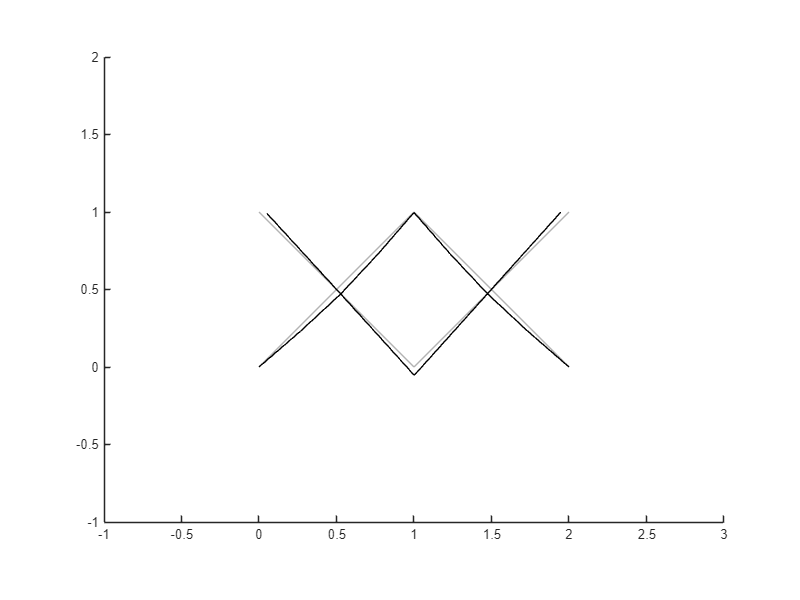

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)),zeros(16,3));

Looking fine. 

Now, let's do the fun thing, we want to remove the first load, change the configuration, deploy this scissor mechanism bridge longer, and reapply the load. 

% Reinitialize will wipe out the previous loading information
assembly.Initialize_Assembly;

% Change the configuration with applied loading
nr_reconfig=Solver_NR_Folding_3N;
nr_reconfig.assembly=assembly;
nr_reconfig.supp=[1,1,1,1;
         2,0,1,1;
         3,0,1,1;
         4,0,1,0;
         5,0,1,0;
         6,0,1,0;
         7,0,1,0;
         8,0,1,0;
         9,0,1,0;
         10,0,1,0;
         11,0,1,0;
         12,0,1,0;
         13,0,1,0;
         14,0,1,0;
         15,0,1,0;
         16,0,1,0;];

% Set up the load
nr_reconfig.target_rot=rot_spr_3N.theta_current_vec;
nr_reconfig.target_rot(13)=pi*0.1;

% Set up the total loading step
nr_reconfig.increStep=60;
% Set up the maximum iteration
nr_reconfig.iterMax=30;
% Set up the tolorence
nr_reconfig.tol=10^-6;

% Solve for the deformation history
Uhis=nr_reconfig.Solve();

Self Assemble Analysis StartIcrement = 1
	Iteration = 1, R = 4.188790e-01 
	Iteration = 2, R = 2.966412e+01 
	Iteration = 3, R = 5.040203e+00 
	Iteration = 4, R = 1.252931e+01 
	Iteration = 5, R = 7.093334e-01 
	Iteration = 6, R = 4.220739e+00 
	Iteration = 7, R = 4.811150e-02 
	Iteration = 8, R = 1.584614e-01 
	Iteration = 9, R = 3.437003e-04 
	Iteration = 10, R = 1.034783e-06 
	Iteration = 11, R = 5.471599e-07 
Icrement = 2
	Iteration = 1, R = 4.166801e-01 
	Iteration = 2, R = 2.820299e+01 
	Iteration = 3, R = 3.771090e+00 
	Iteration = 4, R = 9.775822e+00 
	Iteration = 5, R = 5.565543e-01 
	Iteration = 6, R = 5.454001e+00 
	Iteration = 7, R = 1.249123e-02 
	Iteration = 8, R = 5.926718e-02 
	Iteration = 9, R = 4.409019e-05 
	Iteration = 10, R = 6.997457e-07 
Icrement = 3
	Iteration = 1, R = 4.144705e-01 
	Iteration = 2, R = 2.838589e+01 
	Iteration = 3, R = 8.858133e+00 
	Iteration = 4, R = 6.972842e+00 
	Iteration = 5, R = 1.441825e+00 
	Iteration = 6, R = 3.743793e+00 
	Iteration =

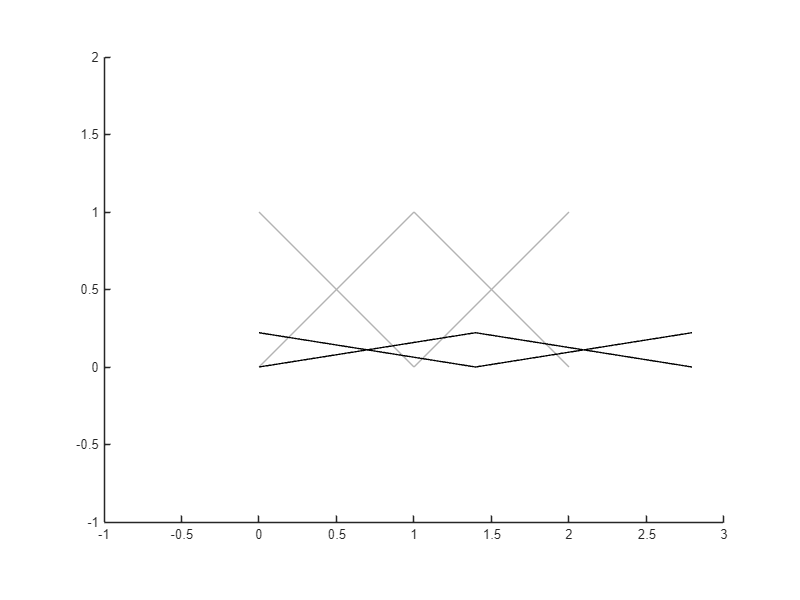

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)),zeros(16,3));

Repeat the loading at the new configuration.

% Solve for the deformation history
Uhis_load=nr.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 7.831810e-02
    Iteration = 2, R = 7.779410e-03
    Iteration = 3, R = 3.261788e-02
    Iteration = 4, R = 2.848249e-03
    Iteration = 5, R = 1.002841e-02
    Iteration = 6, R = 2.079260e-04
    Iteration = 7, R = 1.114741e-04
    Iteration = 8, R = 1.138984e-06
    Iteration = 9, R = 9.334175e-07
Icrement = 2
    Iteration = 1, R = 6.282786e-02
    Iteration = 2, R = 3.853159e-03
    Iteration = 3, R = 1.966776e-02
    Iteration = 4, R = 1.011216e-03
    Iteration = 5, R = 1.641513e-03
    Iteration = 6, R = 5.769866e-06
    Iteration = 7, R = 7.799112e-07
Icrement = 3
    Iteration = 1, R = 1.490804e-01
    Iteration = 2, R = 1.620981e-02
    Iteration = 3, R = 4.363437e-02
    Iteration = 4, R = 1.133968e-02
    Iteration = 5, R = 3.598805e-02
    Iteration = 6, R = 2.521247e-03
    Iteration = 7, R = 1.969483e-02
    Iteration = 8, R = 4.069940e-04
    Iteration = 9, R = 1.190445e-03
    Iteration = 10, R = 3.515356e-04
  

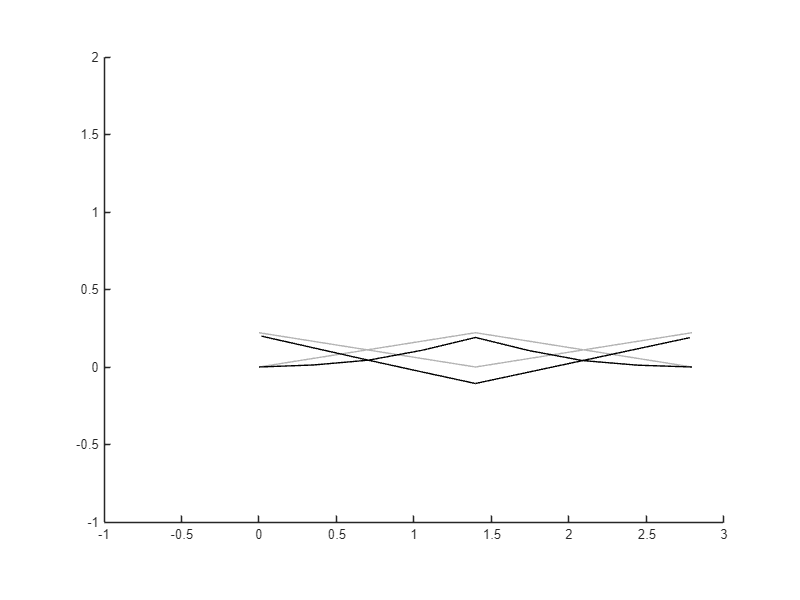

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis_load(end,:,:)),squeeze(Uhis(end,:,:)));

We can see that at the extended configuration, this system is having a much bigger deformation now! This is expected because the total structure height is now lower and the span is also larger. 

This example shows one nice thing about using the lumped parameter model formulations, we can easily capture the large kinematics shape morphing and the load-carrying performance of active structures. It is typically much more difficult to solve the kinematics using Finite Element Methods. 

In addition, we also hope to perform one more step to study how this scissor mechanism fails. This time, we are dealing with bending elements. We shall first recall the bending failure computation from class "Mechanics of Materials". The maximum stress when the rectangular cross section will show up in the top and bottom side with equal magnitude with the value:


$$\sigma_{\max } =\frac{M}{I}\cdot \frac{h}{2}$$


Now, what is the bending moment in the member? It is the stiffness of the spring mutiplying the difference between the stress free angle and the current angle. We can compute the values using the following code:

rot_spr_3N.Solve_Global_Theta(node,squeeze(Uhis_load(end,:,:)));
moment_vec = rot_spr_3N.rot_spr_K_vec.*(rot_spr_3N.theta_current_vec-rot_spr_3N.theta_stress_free_vec);
[maxmoment,index]=max(abs(moment_vec))

maxmoment = 0.3548

index = 11

Based on the result, the maximum moment in the truss is $0\ldotp 3548N\cdot m$ and this moment happens at the #11 three-node rotational hinge. This is the rotational spring at node 8 in the member connecting node 5-15-8-12-3. 

Then, in order to predict the failure load of the scissor mechanism, we need to assume a maximum stress for the material. Since we are using a polymer like material, we can pick 20MPa to be consistent with Section 03. The, the maximum moment the member can hold is:


$$M=\frac{2I\sigma_{\max } }{h}=\frac{2\times \frac{1}{12}{\left(0\ldotp 01m\right)}^4 \times 20\mathrm{MPa}}{0\ldotp 01m}=3\ldotp 3\;N\cdot m$$


Therefore, the maximum load the scissor mechanism can take is:


$$\frac{3\ldotp 3N\cdot m}{0\ldotp 3548N\cdot m}\times \;1N=9\ldotp 3N$$


Thus, if we assume that the bending failure is the dominate failure mode, we can see that this scissor mechanism can take 9.3 Newton of force before it fails in bending. Typically, scissor mechanism is weaker than trusses because the members bend. It is much easier to break a member in bending than in tension or compression. Please also keep in mind that the material and cross section we assume is selected to make the design extremely flimsy. They are not good designs that can carry load, but used to show the nonlinear deformation. 

#### **Practice Problems:**

To practice, please consider further working out the following problems. 

#### **Problem 01 **

Turn this system into a cantilever beam and see what happens. As the following figure:

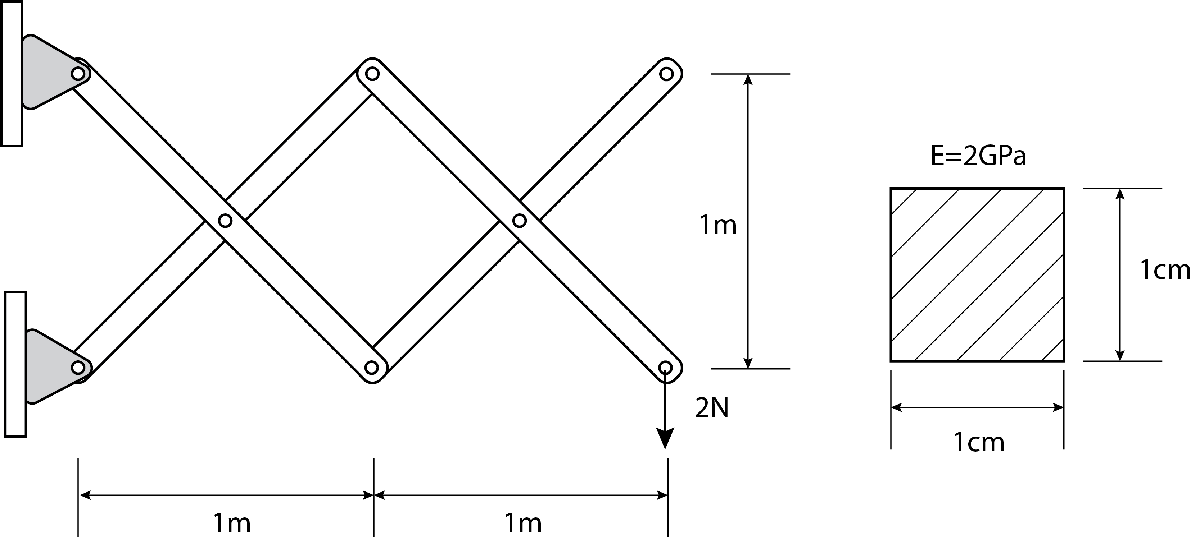

**Problem 02 **

Compute the failure load for the above scissor mechanisms. You may use the same assumption we used in the text. 